%% ===============================================================
%  Plane stress FEM parametric + TWO neural networks predicting full "u" for body forces in x and y direction separately
%  - All comments and printed messages are in English
%  - Input normalized to [-1,1], outputs normalized with z-score (per DOF)
%  - Minibatch training using dlnetwork + Adam
%  - Full inference and comparison with FEM
%  Mesh: 6 x 6 nodes (same as requested)
%  Elastic modulus E = 1, nu = 0.3
% ===============================================================

clear; close all; clc;

%% ===============================================================
% 1️⃣  PROBLEM PARAMETERS AND DOMAIN
% ===============================================================
nNodesX = 8;
nNodesY = 8;
nNodes = nNodesX * nNodesY;

B_min = 1;  B_max = 3;     % base range
H_min = 1;  H_max = 3;     % height range
nSamples = 1000;           % number of geometries for training

% Material (constant)
E = 1;
nu = 0.3;

% Reference unit mesh
[xGrid, yGrid] = meshgrid(linspace(0,1,nNodesX), linspace(0,1,nNodesY));
coords0 = [xGrid(:), yGrid(:)];

% DOF per node and totals
ndofNode = 2;
nDOF = nNodes * ndofNode;

fprintf('Problem: %d nodes (%dx%d) -> %d DOFs\n', nNodes, nNodesX, nNodesY, nDOF);

Problem: 64 nodes (8x8) -> 128 DOFs



tic
%% ===============================================================
% 2️⃣  DATASET CREATION (FEM) - body force applied to entire plate
%     Base (bottom, y==0) is fixed a priori in dataset and training
% ===============================================================
% Body force per unit volume (fx, fy)
bodyForcex = [1; 0];
bodyForcey = [0; 1];

% Preallocate geometry matrix and outputs (outputs = full displacement vector u)
Xdata = zeros(2, nSamples);   % [B; H]
Uall1 = zeros(nDOF,nSamples);
Uall2 = zeros(nDOF,nSamples); % each column is full displacement vector for that sample

fprintf('Generating FEM dataset (%d samples) with base fixed (y==0)...\n', nSamples);

Generating FEM dataset (1000 samples) with base fixed (y==0)...



for i = 1:nSamples
    % random geometric parameters
    B = B_min + (B_max - B_min) * rand();
    H = H_min + (H_max - H_min) * rand();
    Xdata(:,i) = [B; H];

    % physical coordinates scaled
    coords = [coords0(:,1)*B, coords0(:,2)*H];

    % build FEM stiffness and force
    [K1, F1] = buildPlaneStressFEM(coords, nNodesX, nNodesY, E, nu, bodyForcex);
    [K2, F2] = buildPlaneStressFEM(coords, nNodesX, nNodesY, E, nu, bodyForcey);
    
    % identify base nodes (y == 0) -> fixed
    tol = 1e-12;
    baseNodes = find(abs(coords(:,2) - 0) < tol); % bottom side, coords(i,2) → y-coordinate of node i
    fixedDOFs = reshape([ (baseNodes-1)'*ndofNode + 1 ; (baseNodes-1)'*ndofNode + 2 ], [], 1);

    % free DOFs
    allDOFs = (1:nDOF)';
    freeDOFs = setdiff(allDOFs, fixedDOFs);

    % Solve for displacements: u(free) = K_ff \ F_f
    u1 = zeros(nDOF,1);
    u1(freeDOFs) = K1(freeDOFs, freeDOFs) \ F1(freeDOFs);

    u2 = zeros(nDOF,1);
    u2(freeDOFs) = K2(freeDOFs, freeDOFs) \ F2(freeDOFs);

    % Uall(:,i) = u;
    Uall1(:,i) = u1;
    Uall2(:,i) = u2;
end

Ux_energy = norm(Uall2(1:2:end,:),'fro');
Uy_energy = norm(Uall2(2:2:end,:),'fro');
fprintf('Energy ratio Uy/Ux = %.3e\n', Uy_energy/Ux_energy);

Energy ratio Uy/Ux = 1.074e+01



disp('✅ FEM dataset generated.');

✅ FEM dataset generated.


disp('For data generation:');

For data generation:


toc

Elapsed time is 11.047823 seconds.



%% ===============================================================
% 3️⃣  DATA PREPARATION AND NORMALIZATION
%     - Input normalization to [-1,1]
%     - Output normalization: z-score per DOF
% ===============================================================
% Input normalization to [-1,1]
Bnorm = 2*(Xdata(1,:) - B_min)/(B_max - B_min) - 1; 
Hnorm = 2*(Xdata(2,:) - H_min)/(H_max - H_min) - 1;
Xnorm = [Bnorm; Hnorm];

% Output normalization (z-score) per DOF (row-wise)
epsVal = 1e-8;

mu_U1 = mean(Uall1,2);
sigma_U1 = std(Uall1,0,2) + epsVal; 
Uall_norm1 = (Uall1 - mu_U1) ./ sigma_U1;

mu_U2 = mean(Uall2,2); 
sigma_U2 = std(Uall2,0,2) + epsVal;
Uall_norm2 = (Uall2 - mu_U2) ./ sigma_U2;

% Convert to single for speed (optional)
Xn = single(Xnorm);
Un1 = single(Uall_norm1);
Un2 = single(Uall_norm2);

% Create dlarray for input when needed; minibatches will be formed manually
dlXall = dlarray(Xn, "CB"); 

tic
%% ===============================================================
% 4️⃣  DEFINE NETWORKs (mapping 2 -> nDOF)
% ===============================================================
% Simple fully-connected network for body force x (NN1)
nOut1 = nDOF;
nOut2 = nDOF;

layers1 = [
    featureInputLayer(2,"Normalization","none") %2 input features;
    fullyConnectedLayer(64)
    % tanhLayer
    reluLayer
    fullyConnectedLayer(64)
    % tanhLayer
    reluLayer
    fullyConnectedLayer(nOut1)
];
dlnet1 = dlnetwork(layerGraph(layers1));

% Simple fully-connected network for body force y (NN2)
layers2 = [
    featureInputLayer(2,"Normalization","none") %2 input features;
    fullyConnectedLayer(64)
    % tanhLayer
    reluLayer
    fullyConnectedLayer(64)
    % tanhLayer
    reluLayer
    fullyConnectedLayer(nOut2)
];
dlnet2 = dlnetwork(layerGraph(layers2));

%% ===============================================================
% 5️⃣  TRAINING (minibatch) - manual loop with Adam
%% ===============================================================
numEpochs = 1000;
learnRate = 1e-3; 
miniBatchSize = 200;

avgGrad1 = [];
avgSqGrad1 = []; 
avgGrad2 = [];
avgSqGrad2 = [];

numIterationsPerEpoch = ceil(nSamples / miniBatchSize);

disp('🚀 Starting training single network (minibatch Adam)...');

🚀 Starting training single network (minibatch Adam)...



for epoch = 1:numEpochs
    idx = randperm(nSamples);

    for it = 1:numIterationsPerEpoch
        batchStart = (it-1)*miniBatchSize + 1;
        batchEnd = min(it*miniBatchSize, nSamples);
        batchIdx = idx(batchStart:batchEnd);

        % form minibatch
        Xbatch = dlarray(Xn(:,batchIdx), "CB");
        Ybatch1 = dlarray(Un1(:,batchIdx), "CB");
        Ybatch2 = dlarray(Un2(:,batchIdx), "CB");

        % compute loss and gradients for NN1 & NN2
        [loss1, gradients1] = dlfeval(@modelLoss, dlnet1, Xbatch, Ybatch1);
        [loss2, gradients2] = dlfeval(@modelLoss, dlnet2, Xbatch, Ybatch2);

        % update network parameters for NN1 & NN2 with Adam
        iteration = (epoch-1)*numIterationsPerEpoch + it;
        [dlnet1, avgGrad1, avgSqGrad1] = adamupdate(dlnet1, gradients1, avgGrad1, avgSqGrad1, iteration, learnRate);
        [dlnet2, avgGrad2, avgSqGrad2] = adamupdate(dlnet2, gradients2, avgGrad2, avgSqGrad2, iteration, learnRate);


    end

    if mod(epoch,100)==0 || epoch==1
        fprintf('Epoch %d/%d - Loss (NN1) %.3e ; Loss (NN2) %.3e\n', epoch, numEpochs, gather(extractdata(loss1)),  gather(extractdata(loss2)));
    end

    % optional LR schedule
    if epoch == round(0.7*numEpochs)
        learnRate = learnRate * 0.2;
        fprintf('Learning rate decreased to %.2e at epoch %d\n', learnRate, epoch);
    end
end

Epoch 1/1000 - Loss (NN1) 8.931e-01 ; Loss (NN2) 8.449e-01
Epoch 100/1000 - Loss (NN1) 2.613e-03 ; Loss (NN2) 2.193e-03
Epoch 200/1000 - Loss (NN1) 5.488e-04 ; Loss (NN2) 6.290e-04
Epoch 300/1000 - Loss (NN1) 1.838e-04 ; Loss (NN2) 2.709e-04
Epoch 400/1000 - Loss (NN1) 1.324e-04 ; Loss (NN2) 1.593e-04
Epoch 500/1000 - Loss (NN1) 1.792e-04 ; Loss (NN2) 1.301e-04
Epoch 600/1000 - Loss (NN1) 7.825e-05 ; Loss (NN2) 8.047e-05
Epoch 700/1000 - Loss (NN1) 8.272e-05 ; Loss (NN2) 7.615e-05


Learning rate decreased to 2.00e-04 at epoch 700


Epoch 800/1000 - Loss (NN1) 6.416e-05 ; Loss (NN2) 6.677e-05
Epoch 900/1000 - Loss (NN1) 4.669e-05 ; Loss (NN2) 5.861e-05
Epoch 1000/1000 - Loss (NN1) 4.060e-05 ; Loss (NN2) 4.610e-05



disp('✅ Training completed.');

✅ Training completed.



% Save trained network and normalization data for NN1
save(['single_net_fullu_', num2str(nNodesX),'x',num2str(nNodesY), '.mat'], ...
    'dlnet1','B_min','B_max','H_min','H_max','mu_U1','sigma_U1', ...
    'nNodesX','nNodesY','E','nu','ndofNode');

% Save trained network and normalization data for NN2
save(['single_net_fullu_', num2str(nNodesX),'x',num2str(nNodesY), '.mat'], ...
    'dlnet2','B_min','B_max','H_min','H_max','mu_U2','sigma_U2', ...
    'nNodesX','nNodesY','E','nu','ndofNode');

disp('For training:');

For training:


toc

Elapsed time is 67.643130 seconds.


% Global text formatting configuration
set(groot, ...
    'DefaultAxesFontSize', 18, ...     % For ticks, x/y/z labels
    'DefaultTextFontSize', 20, ...     % For manually added text objects
    'DefaultLegendFontSize', 20);      % For graph legends

% set(findall(gcf,'-property','FontSize'),'FontSize',14)

tic
%% ===============================================================
%  INFERENCE + COMPARISON WITH FEM
%  (we predict full u from the single network, then de-normalize)
% ===============================================================

% change these 4 parameters for testing
Btest = 1.25;
Htest = 2.0;
bodyforcetestx = [2;0];
bodyforcetesty = [0;3];

% --- Normalize geometry input ---
Bnorm_t = 2*(Btest - B_min)/(B_max - B_min) - 1;
Hnorm_t = 2*(Htest - H_min)/(H_max - H_min) - 1;
dlGeom = dlarray(single([Bnorm_t; Hnorm_t]), "CB");

% --- Predict normalized u for body force x & y (NN1 & NN2) ---
u_norm_dl1 = predict(dlnet1, dlGeom);
u_norm1 = double(extractdata(u_norm_dl1));
u_norm_dl2 = predict(dlnet2, dlGeom);
u_norm2 = double(extractdata(u_norm_dl2));

% --- De-normalize to physical scale ---
u_pred1 = (u_norm1 .* mu_U1*0 + 0); 
u_pred1 = (u_norm1 .* sigma_U1) + mu_U1;
u_pred1 = u_pred1 .* bodyforcetestx(1);

u_pred2 = (u_norm2 .* mu_U2*0 + 0); 
u_pred2 = (u_norm2 .* sigma_U2) + mu_U2;
u_pred2 = u_pred2 .* bodyforcetesty(2);

disp('Inference time:')

Inference time:


toc

Elapsed time is 0.755450 seconds.



% --- FEM solution for the same geometry (base fixed) ---
coords = [coords0(:,1)*Btest, coords0(:,2)*Htest];
[K1, F1] = buildPlaneStressFEM(coords, nNodesX, nNodesY, E, nu, bodyforcetestx);
[K2, F2] = buildPlaneStressFEM(coords, nNodesX, nNodesY, E, nu, bodyforcetesty);

% apply base fixed BC (y==0)
tol = 1e-12;
baseNodes = find(abs(coords(:,2) - 0) < tol);
fixedDOFs = reshape([ (baseNodes-1)'*ndofNode + 1 ; (baseNodes-1)'*ndofNode + 2 ], [], 1);
allDOFs = (1:nDOF)';
freeDOFs = setdiff(allDOFs, fixedDOFs);

u_fem1 = zeros(nDOF,1);
u_fem2 = zeros(nDOF,1);

u_fem1(freeDOFs) = K1(freeDOFs, freeDOFs) \ F1(freeDOFs);
u_fem2(freeDOFs) = K2(freeDOFs, freeDOFs) \ F2(freeDOFs);

% --- Compare FEM vs NN ---
u_NN1= u_pred1(:);
u_FEM1 = u_fem1(:);
u_NN2 = u_pred2(:);
u_FEM2 = u_fem2(:);

% extract u_x and u_y components
u_x_FEM1 = u_FEM1(1:2:end);
u_y_FEM1 = u_FEM1(2:2:end);
u_x_NN1  = u_NN1(1:2:end);
u_y_NN1  = u_NN1(2:2:end);

u_x_FEM2 = u_FEM2(1:2:end);
u_y_FEM2 = u_FEM2(2:2:end);
u_x_NN2  = u_NN2(1:2:end);
u_y_NN2  = u_NN2(2:2:end);

% reshape on grid
Xcoords = reshape(coords(:,1), nNodesY, nNodesX);
Ycoords = reshape(coords(:,2), nNodesY, nNodesX);

UxF1 = reshape(u_x_FEM1, nNodesY, nNodesX);
UyF1 = reshape(u_y_FEM1, nNodesY, nNodesX);
UxN1 = reshape(u_x_NN1,  nNodesY, nNodesX);
UyN1 = reshape(u_y_NN1,  nNodesY, nNodesX);

UxF2 = reshape(u_x_FEM2, nNodesY, nNodesX);
UyF2 = reshape(u_y_FEM2, nNodesY, nNodesX);
UxN2 = reshape(u_x_NN2,  nNodesY, nNodesX);
UyN2 = reshape(u_y_NN2,  nNodesY, nNodesX);

UxF = UxF1 + UxF2;
UyF = UyF1 + UyF2;
UxN = UxN1 + UxN2;
UyN = UyN1 + UyN2;

%error
Err_u = abs(UxF - UxN);
Err_v = abs(UyF - UyN);
% Err_u1 = abs(UxF1 - UxN1);
% Err_v1 = abs(UyF1 - UyN1);
% Err_u2 = abs(UxF2 - UxN2);
% Err_v2 = abs(UyF2 - UyN2);

%figures for NN1
fprintf('Figures for NN1 (body force x = %d):', bodyforcetestx(1));

Figures for NN1 (body force x = 2):

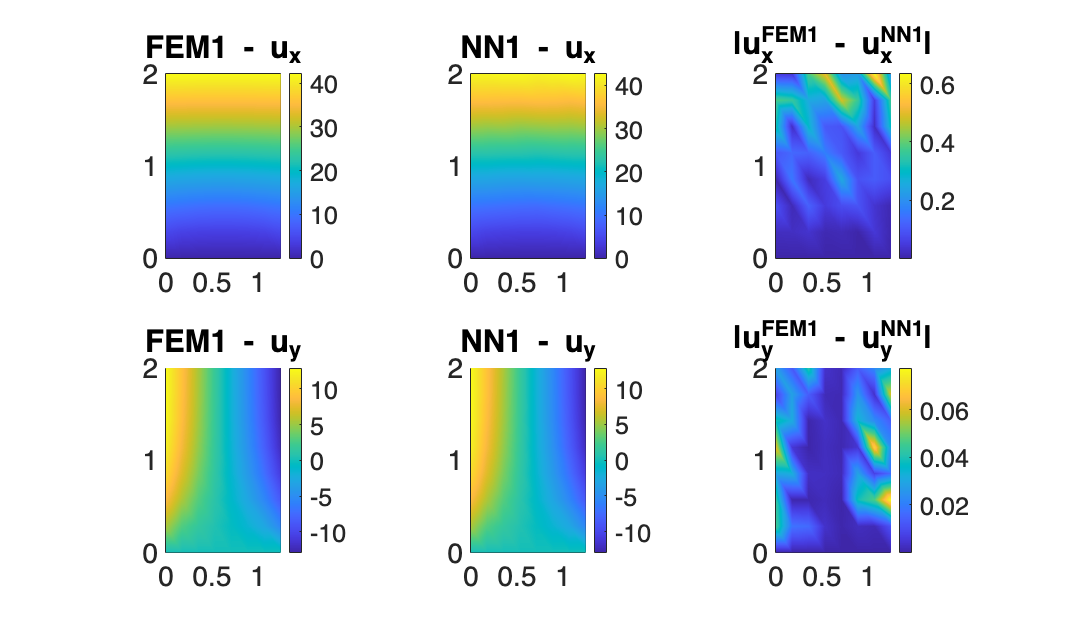

figure('Position',[100 100 1400 800]);

subplot(2,3,1);
pcolor(Xcoords, Ycoords, UxF1); shading interp; colorbar; axis equal tight;
title('FEM1 - u_x');

subplot(2,3,2);
pcolor(Xcoords, Ycoords, UxN1); shading interp; colorbar; axis equal tight;
title('NN1 - u_x');

subplot(2,3,3);
pcolor(Xcoords, Ycoords, abs(UxF1 - UxN1)); shading interp; colorbar; axis equal tight;
title('|u_x^{FEM1} - u_x^{NN1}|');

subplot(2,3,4);
pcolor(Xcoords, Ycoords, UyF1); shading interp; colorbar; axis equal tight;
title('FEM1 - u_y');

subplot(2,3,5);
pcolor(Xcoords, Ycoords, UyN1); shading interp; colorbar; axis equal tight;
title('NN1 - u_y');

subplot(2,3,6);
pcolor(Xcoords, Ycoords, abs(UyF1 - UyN1)); shading interp; colorbar; axis equal tight;
title('|u_y^{FEM1} - u_y^{NN1}|');



%figures for NN2
fprintf('Figures for NN2 (body force y = %d):', bodyforcetesty(2))

Figures for NN2 (body force y = 3):

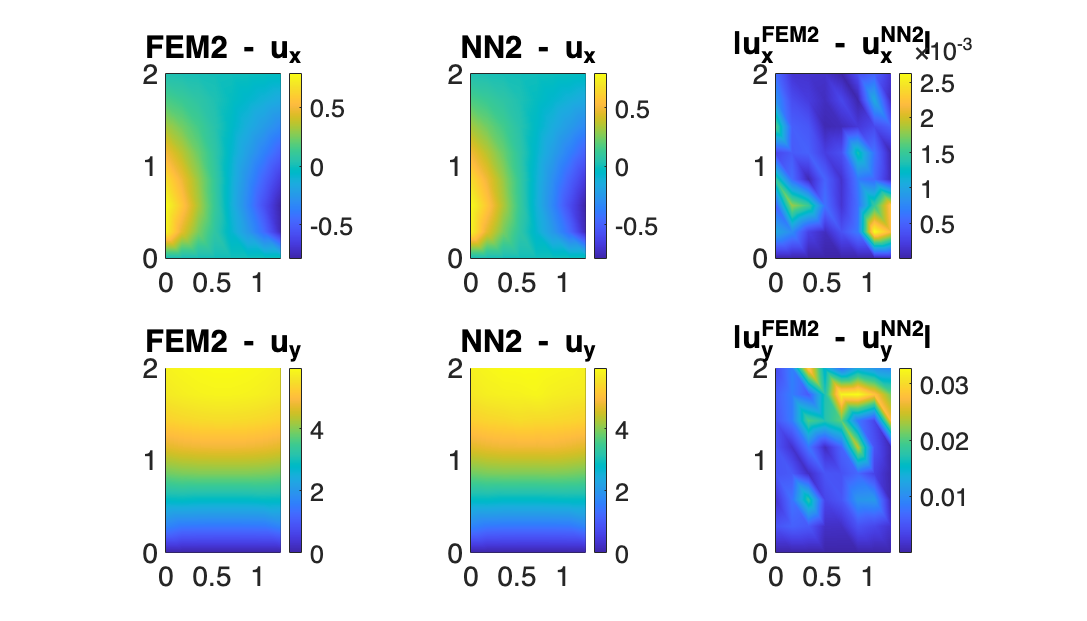

figure('Position',[100 100 1400 800]);

subplot(2,3,1);
pcolor(Xcoords, Ycoords, UxF2); shading interp; colorbar; axis equal tight;
title('FEM2 - u_x');

subplot(2,3,2);
pcolor(Xcoords, Ycoords, UxN2); shading interp; colorbar; axis equal tight;
title('NN2 - u_x');

subplot(2,3,3);
pcolor(Xcoords, Ycoords, abs(UxF2 - UxN2)); shading interp; colorbar; axis equal tight;
title('|u_x^{FEM2} - u_x^{NN2}|');

subplot(2,3,4);
pcolor(Xcoords, Ycoords, UyF2); shading interp; colorbar; axis equal tight;
title('FEM2 - u_y');

subplot(2,3,5);
pcolor(Xcoords, Ycoords, UyN2); shading interp; colorbar; axis equal tight;
title('NN2 - u_y');

subplot(2,3,6);
pcolor(Xcoords, Ycoords, abs(UyF2 - UyN2)); shading interp; colorbar; axis equal tight;
title('|u_y^{FEM2} - u_y^{NN2}|');



%figures
disp('Figures for combined displacements:')

Figures for combined displacements:


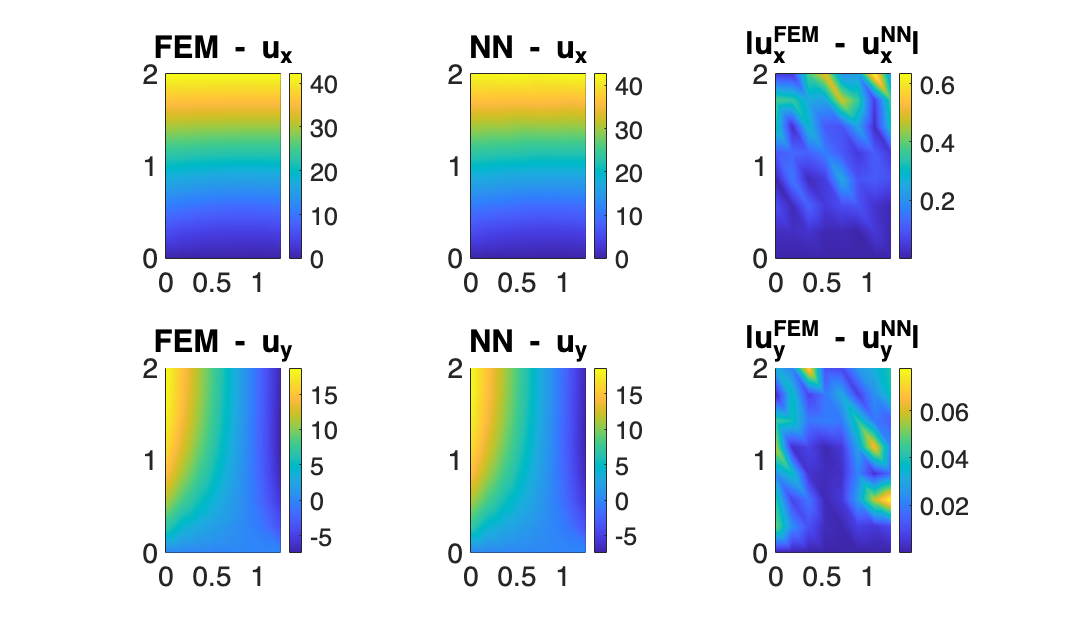

figure('Position',[100 100 1400 800]);

subplot(2,3,1);
pcolor(Xcoords, Ycoords, UxF); shading interp; colorbar; axis equal tight;
title('FEM - u_x');

subplot(2,3,2);
pcolor(Xcoords, Ycoords, UxN); shading interp; colorbar; axis equal tight;
title('NN - u_x');

subplot(2,3,3);
pcolor(Xcoords, Ycoords, Err_u); shading interp; colorbar; axis equal tight;
title('|u_x^{FEM} - u_x^{NN}|');

subplot(2,3,4);
pcolor(Xcoords, Ycoords, UyF); shading interp; colorbar; axis equal tight;
title('FEM - u_y');

subplot(2,3,5);
pcolor(Xcoords, Ycoords, UyN); shading interp; colorbar; axis equal tight;
title('NN - u_y');

subplot(2,3,6);
pcolor(Xcoords, Ycoords, Err_v); shading interp; colorbar; axis equal tight;
title('|u_y^{FEM} - u_y^{NN}|');


% Errors 
u_FEM = u_FEM1 + u_FEM2;
u_NN  = u_NN1  + u_NN2;

err_vec = u_FEM - u_NN;
e = err_vec;
u_ref = u_FEM;

RMSE   = norm(e) / sqrt(numel(e));
relL2  = norm(e) / norm(u_ref);
maxErr = norm(e, Inf) / norm(u_ref, Inf);

fprintf('RMSE   : %.3e\n', RMSE);

RMSE   : 1.397e-01


fprintf('Relative L2 error : %.3e\n', relL2);

Relative L2 error : 7.668e-03


fprintf('Relative Infinity norm error: %.3e\n', maxErr);

Relative Infinity norm error: 1.505e-02



% % Errors for NN1 and NN2
% RMSE_1 = norm(u_FEM1 - u_NN1) / sqrt(numel(u_FEM1 - u_NN1));
% relL2_1 = norm(u_FEM1 - u_NN1) / norm(u_FEM1);
% maxErr_1 = norm(u_FEM1 - u_NN1, Inf) / norm(u_FEM1, Inf);
% 
% fprintf('RMSE (NN1)      : %.3e\n', RMSE_1);
% fprintf('Relative L2 error (NN1)  : %.3e\n', relL2_1);
% fprintf('Relative Infinity norm error (NN1)      : %.3e\n', maxErr_1); %maximum error
% 
% RMSE_2 = norm(u_FEM2 - u_NN2) / sqrt(numel(u_FEM2 - u_NN2));
% relL2_2 = norm(u_FEM2 - u_NN2) / norm(u_FEM2);
% maxErr_2 = norm(u_FEM2 - u_NN2, Inf) / norm(u_FEM2, Inf);
% 
% fprintf('RMSE (NN2)      : %.3e\n', RMSE_2);
% fprintf('Relative L2 error (NN2)  : %.3e\n', relL2_2);
% fprintf('Relative Infinity norm error (NN2)      : %.3e\n', maxErr_2); %maximum error

disp('✅ Verification completed.');

✅ Verification completed.


disp('For plotting:');

For plotting:


toc

Elapsed time is 5.246081 seconds.



% exportgraphics(gcf,'figure_name.png','Resolution',300)

===============================================================

Local functions

===============================================================


function [K,F] = buildPlaneStressFEM(coords,nx,ny,E,nu,bodyForce)
    % Structured mesh of 4-node bilinear quadrilateral elements
    nNodes = nx*ny;
    nElemX = nx-1; nElemY = ny-1;
    nElem = nElemX * nElemY;
    ndofNode = 2;
    nDOF = nNodes * ndofNode; %total dof of system

    % element connectivity matrix
    %(ix, iy) is one quadrilateral element
    conn = zeros(nElem,4);
    for ix = 1:nElemX
        for jy = 1:nElemY
            n1 = (ix-1)*ny + jy;
            n2 = ix*ny + jy;
            n3 = ix*ny + (jy+1);
            n4 = (ix-1)*ny + (jy+1);
            e = (ix-1)*nElemY + jy; %This converts the 2D element index (ix, jy) into a single element number
            conn(e,:) = [n1 n2 n3 n4]; %Element e connects nodes n1, n2, n3, n4
        end
    end

    K = zeros(nDOF);
    F = zeros(nDOF,1);

    % Plane stress constitutive matrix
    D = E / (1 - nu^2) * [1, nu, 0;
                          nu, 1, 0;
                          0, 0, (1-nu)/2];

    % 2x2 Gauss
    gp = [-1/sqrt(3), 1/sqrt(3)];
    wgp = [1,1];

    for e = 1:nElem
        nodes = conn(e,:);
        xe = coords(nodes,1);
        ye = coords(nodes,2);

        %element stiffness and force matrix
        Ke = zeros(8,8);
        Fe = zeros(8,1);

        % Reduced integration term B0 for shear (as in original)
        xi = 0; eta = 0;
        [N0, dNdxi0, dNdeta0] = shape4(xi,eta);
        J0 = [dNdxi0'; dNdeta0'] * [xe, ye];
        detJ0 = det(J0);
        invJ0 = inv(J0);
        dN0 = [dNdxi0, dNdeta0] * invJ0;

        B0 = zeros(3,8);
        for a = 1:4
            dNx = dN0(a,1);
            dNy = dN0(a,2);
            col = (a-1)*2;
            B0(1, col + 1) = dNx;
            B0(2, col + 2) = dNy;
            B0(3, col + 1) = dNy;
            B0(3, col + 2) = dNx;
        end

        for i = 1:2
            for j = 1:2
                xi = gp(i); eta = gp(j);
                [N, dNdxi, dNdeta] = shape4(xi,eta);
                J = [dNdxi'; dNdeta'] * [xe, ye];
                detJ = det(J);
                invJ = inv(J);
                dN = [dNdxi, dNdeta] * invJ;

                B = zeros(3,8);
                for a = 1:4
                    dNx = dN(a,1);
                    dNy = dN(a,2);
                    col = (a-1)*2;
                    B(1, col + 1) = dNx;
                    B(2, col + 2) = dNy;
                    B(3, col + 1) = dNy;
                    B(3, col + 2) = dNx;
                end

                % replace shear row with reduced B0 shear row
                B(3,:) = B0(3,:);

                Ke = Ke + (B' * D * B) * detJ * wgp(i) * wgp(j);

                Nmat = zeros(2,8);
                for a = 1:4
                    Nmat(1, (a-1)*2 + 1) = N(a);
                    Nmat(2, (a-1)*2 + 2) = N(a);
                end
                Fe = Fe + (Nmat' * bodyForce) * detJ * wgp(i) * wgp(j);
            end
        end

        % assemble
        gdofs = zeros(8,1);
        for a = 1:4
            node = nodes(a);
            gdofs((a-1)*2 + (1:2)) = (node-1)*2 + (1:2);
        end
        K(gdofs, gdofs) = K(gdofs, gdofs) + Ke;
        F(gdofs) = F(gdofs) + Fe;
    end
end

function [N, dNdxi, dNdeta] = shape4(xi,eta)
    N = 0.25*[(1-xi)*(1-eta);
              (1+xi)*(1-eta);
              (1+xi)*(1+eta);
              (1-xi)*(1+eta)];
    dNdxi  = 0.25*[-(1-eta); (1-eta); (1+eta); -(1+eta)];
    dNdeta = 0.25*[-(1-xi); -(1+xi); (1+xi);  (1-xi)];
end

function [loss,gradients] = modelLoss(dlnet,X,Y)
    % Simple MSE loss for single network
    Ypred = forward(dlnet,X);
    loss = mean((Ypred - Y).^2,'all');
    gradients = dlgradient(loss, dlnet.Learnables);
end
